filtBanks.fs44100 = gammatoneFilterBank([50 20000],64,44100);
filtBanks.fs48000 = gammatoneFilterBank([50 20000],64,48000);

TURMER_mrcgTrain = buildRawMrcgMatrix(class1,filtBanks);
LUSMEG_mrcgTrain = buildRawMrcgMatrix(class2,filtBanks);

[XTrain, YTrain] = createFeatureCells(TURMER_mrcgTrain, LUSMEG_mrcgTrain);

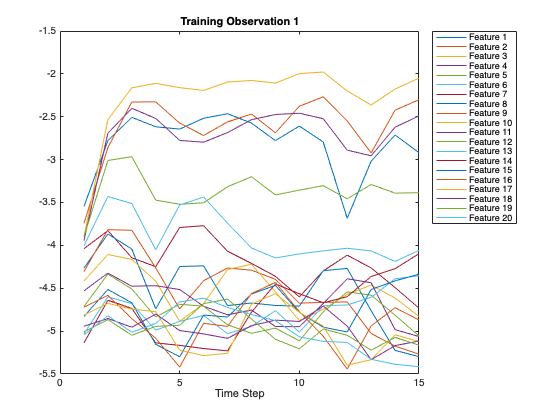

figure
plot(XTrain{1}(1:20,:)')
xlabel("Time Step")
title("Training Observation 1")
numFeatures = size(XTrain{1},1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")

filterSize = 3;
numFilters = 32;

layers = [ ...
    sequenceInputLayer(numFeatures)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    globalAveragePooling1dLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

[XTrain, YTrain, XValidation, YValidation] = createValidationSplit(XTrain, YTrain);

options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=150, ...
    SequencePaddingDirection="left", ...
    ValidationData={XValidation,YValidation}, ...
    Plots="training-progress", ...
    Verbose=0);

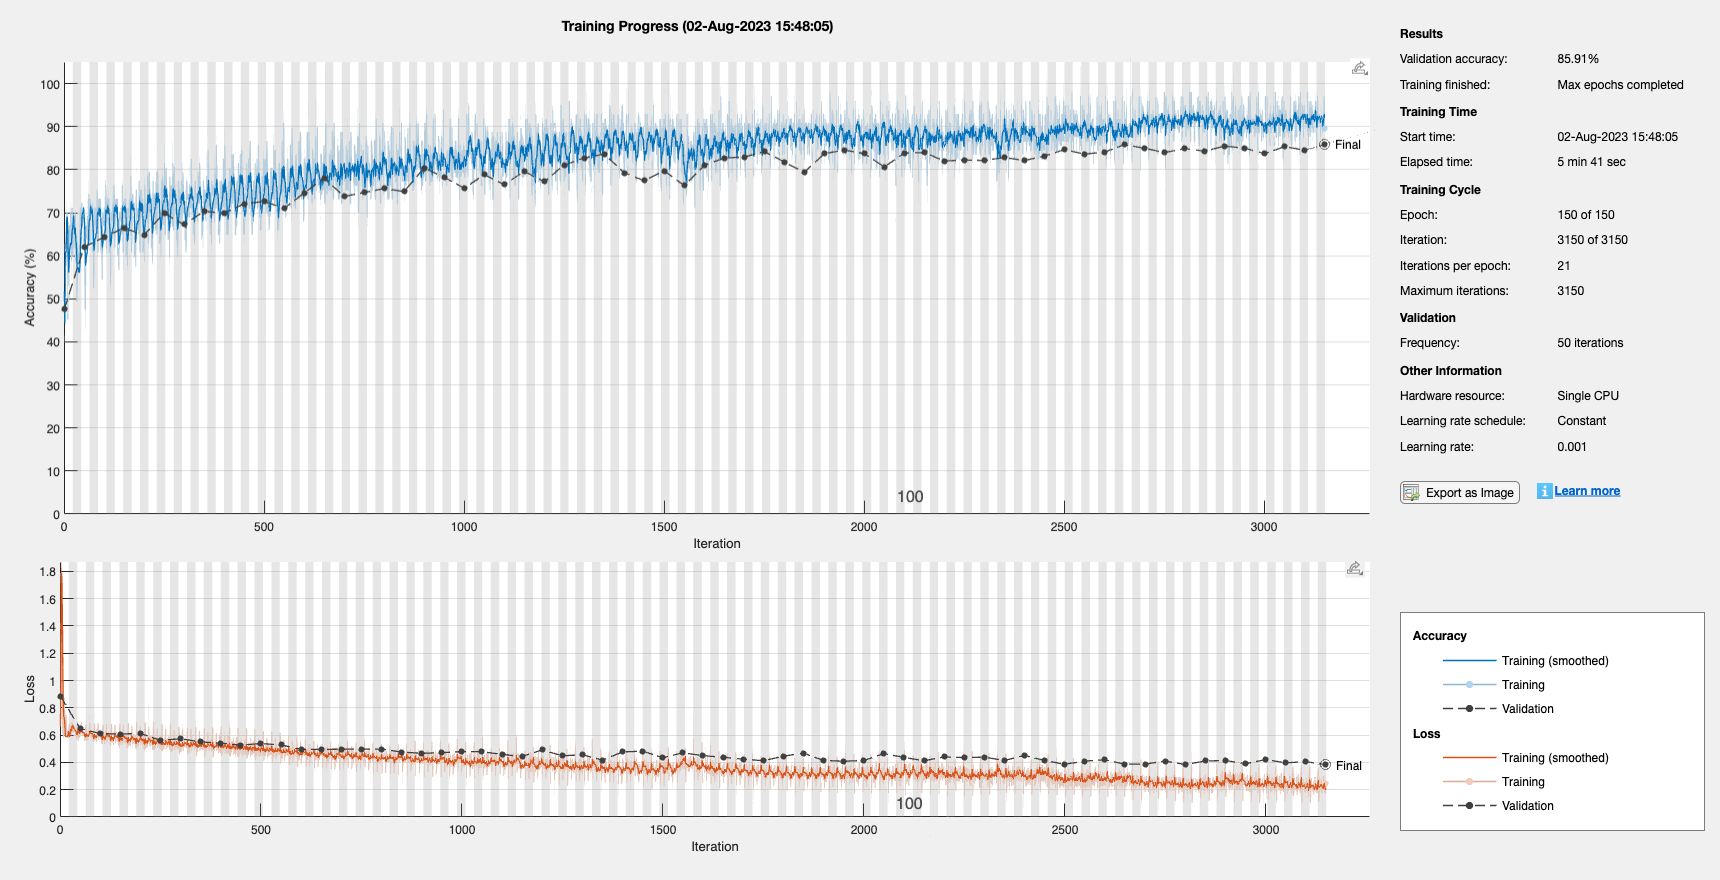

mrcgCNNNet = trainNetwork(XTrain,YTrain,layers,options);

XTest = cat(1,TURMER_mrcgTest,LUSMEG_mrcgTest);
YTest = ones(size(XTest,1),1);
YTest(1:size(TURMER_mrcgTest,1)) = -1;
YTest = categorical(YTest, [-1, 1], {class1,class2});

YPred = classify(mrcgCNNNet,XTest, ...
    MiniBatchSize=miniBatchSize, ...
    SequencePaddingDirection="left");

acc = mean(YPred == YTest)

acc = 0.7726

## Trying MFCC

[XTrain, YTrain] = createFeatureCells(TURMER_mfccTrain,LUSMEG_mfccTrain,class1,class2);
[XTrain, YTrain, XValidation, YValidation] = createValidationSplit(XTrain, YTrain);
[XTest, YTest] = createFeatureCells(TURMER_mfccTest,LUSMEG_mfccTest,class1,class2);

numFeatures = 14;
filterSize = 3;
numFilters = 32;

layers = [ ...
    sequenceInputLayer(numFeatures)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    globalAveragePooling1dLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=150, ...
    SequencePaddingDirection="left", ...
    ValidationData={XValidation,YValidation}, ...
    Plots="training-progress", ...
    Verbose=0);

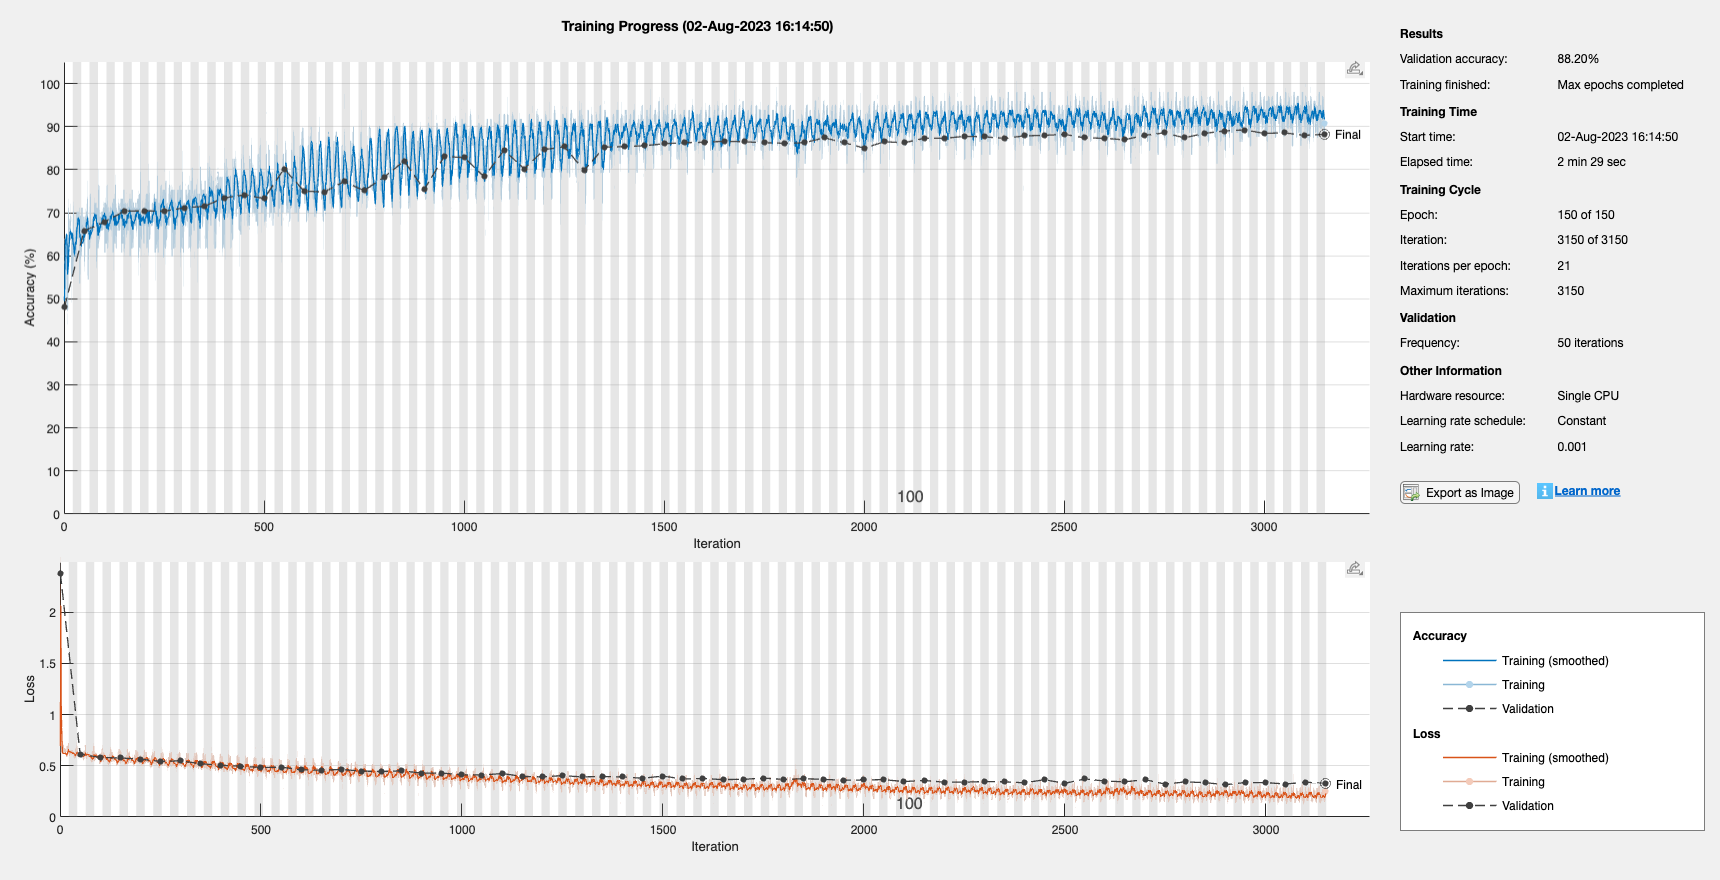

mfccCNNNet = trainNetwork(XTrain,YTrain,layers,options);

YPred = classify(mfccCNNNet,XTest, ...
    MiniBatchSize=miniBatchSize, ...
    SequencePaddingDirection="left");

acc = mean(YPred == YTest)

acc = 0.7769